# Calcolo Numerico con Laboratorio

# Compito a casa 

# 27 settembre 2021

## Esercizio 1 

Si consideri la funzione $f(x)=x^2+\frac{10}{\sin(x)+1.2}$ per $x\in[-2,8]$.

Per `n=2:12`, eseguire le seguenti operazioni:

1. Interpolare la funzione nell'intervallo assegnato con i polinomi di grado `n`, costruiti usando $n+1$ nodi di Chebyshev e $n+1$ punti equidistanti .

2. Usando il comando subplot riportare 3 grafici contenenti rispettivamente: 

- la funzione e il polinomio interpolatore con nodi equidistanti;

- la funzione e il polinomio interpolatore con nodi di Chebyshev;

- la funzione e i due polinomi interpolatori.

3. Calcolare per ciascun valore di $n$ l'errore commesso usando i polinomi con nodi equidistanti e con nodi di Chebyshev.

4. Riportare gli errori per i due polinomi in uno stesso grafico in scala semilogaritmica.

Allegare la function `chebyshev` utilizzata per eseguire l'esercizio e la figura contenente gli errori.

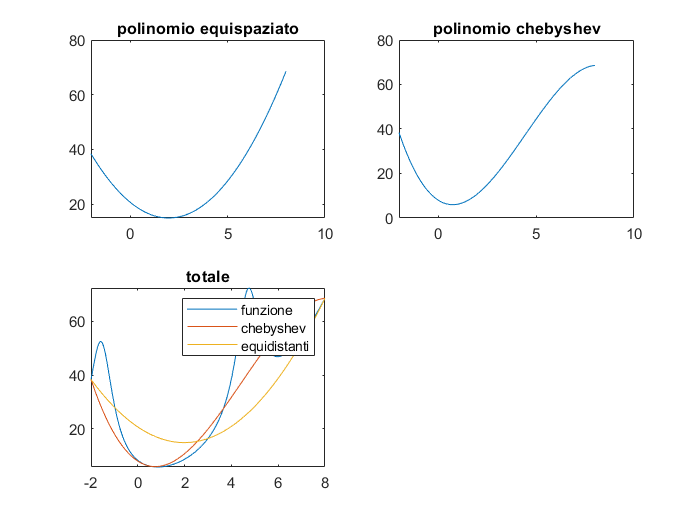

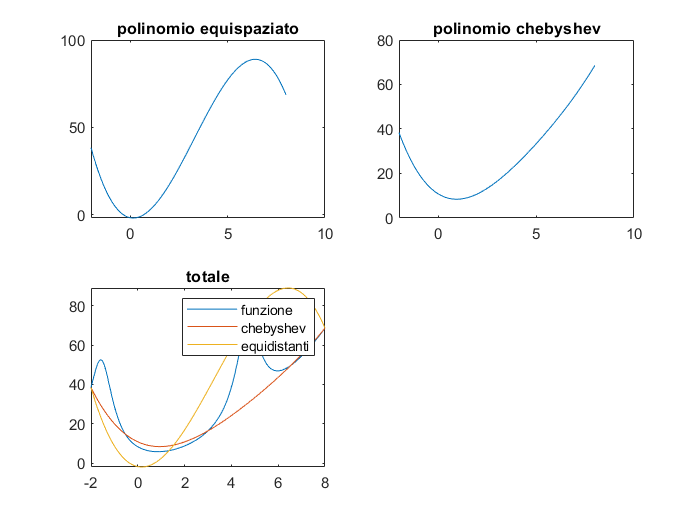

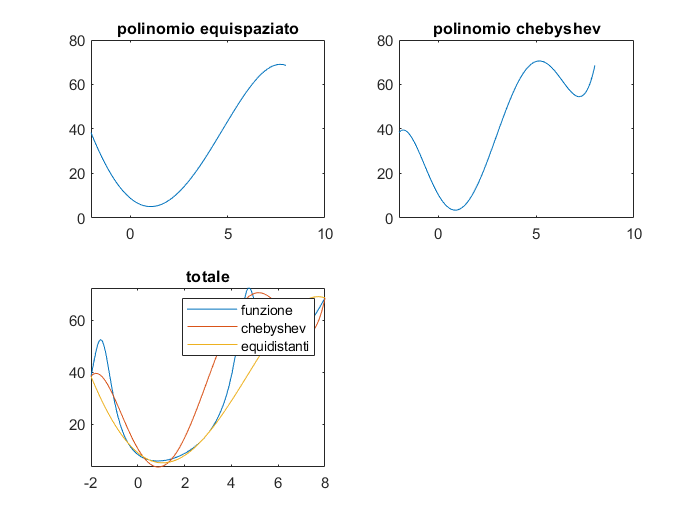

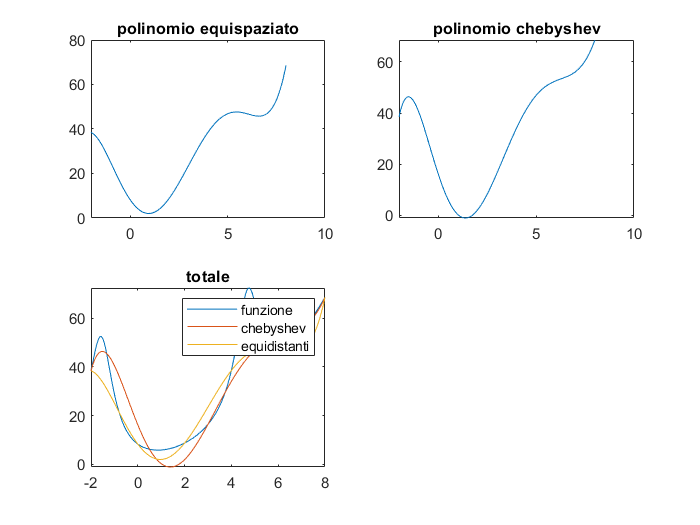

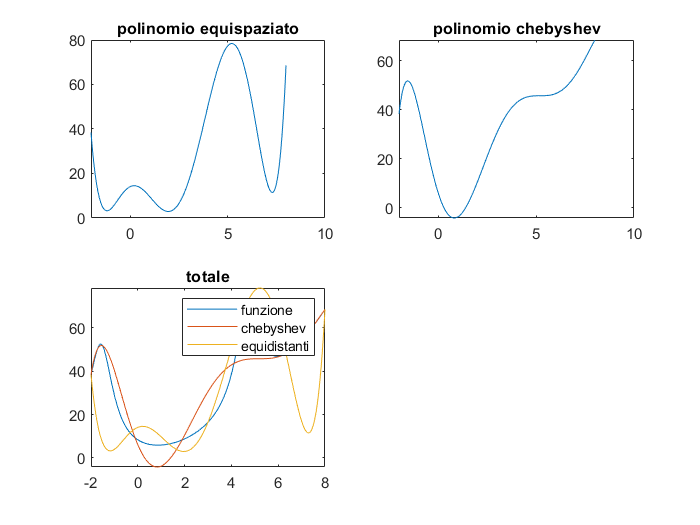

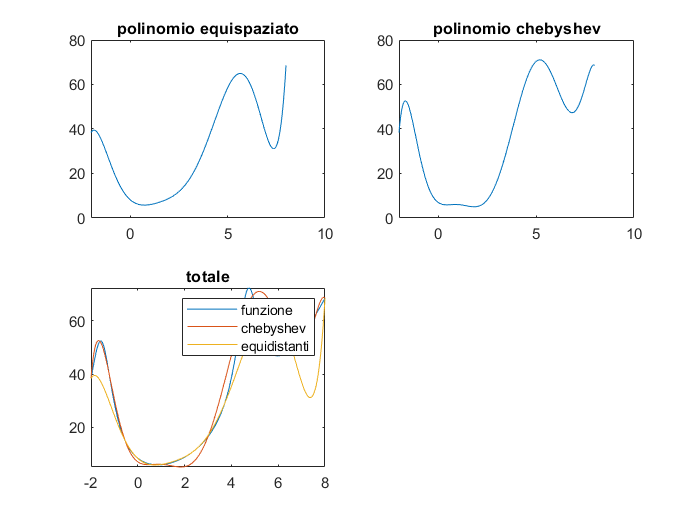

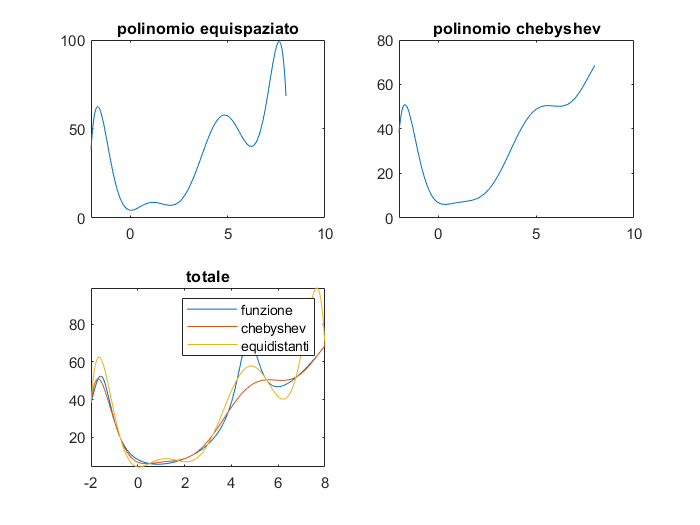

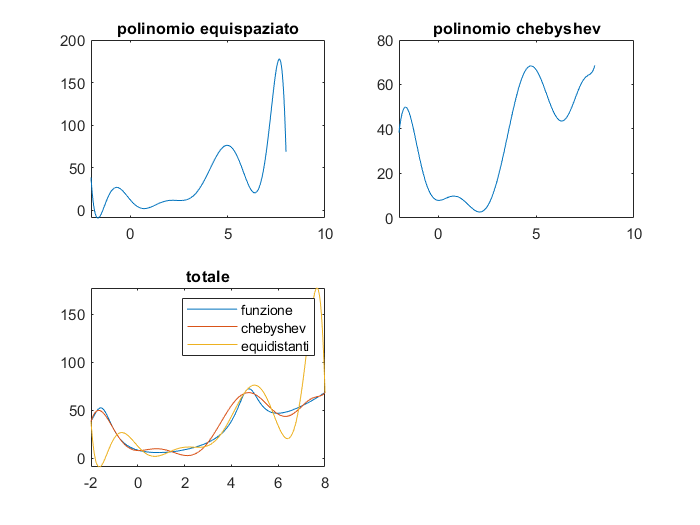

clear all
f=@(x) x.^2+10./(sin(x)+1.2);
N=100;
a=-2;b=8;
z=linspace(a,b,N);
E=[];Ec=[];
for n=2:12
    figure("Name","grado= "+n)
    pc=chebyshev(n+1,a,b,f);
    p=calcPoly([a b],n,f);
    subplot(2,2,1)
    plotPoly(p,[a b],"")
    title("polinomio equispaziato")
    subplot(2,2,2)
    plotPoly(pc,[a b],"")
    title("polinomio chebyshev")
    subplot(2,2,3)
    fplot(f,[a b])
    hold on
    plotPoly(pc,[a b],"")
    plotPoly(p,[a b],"")
    title("totale")
    legend("funzione","chebyshev","equidistanti")
    E=[E norm(f(z)-polyval(p,z),inf)];
    Ec=[Ec norm(f(z)-polyval(pc,z),inf)];
end

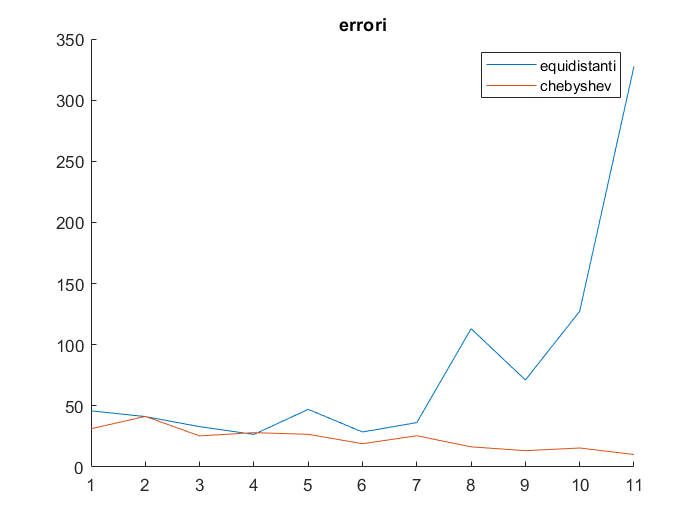

figure
hold on
semilogy(E)
semilogy(Ec)
title("errori")
legend("equidistanti","chebyshev")

## Esercizio 2

Si consideri la funzione $f(x)=x\cos(x)$ per $x\in[-1,1]$.

- Costruire il polinomio interpolatore utilizzando 22 nodi equispaziati $x_i$, $i=0,\dots,21$.

- Generare un vettore di valori approssimati $\hat y_i=f(x_i)+p_i$ essendo $p$ un vettore della stessa dimensione di $f(x)$generato in maniera casuale e tale che  $\max_{i=0,\dots,21}|p_i|\approx 10^{-3}$. Usare a tale scopo il comando `rand(n,m)` che produce un array di dimensione `n x m` di numeri casuali compresi tra 0 e 1.

- Costruire il polinomio interpolatore utilizzando i valori perturbati.

- Riportare in uno stesso grafico la funzione data e i due polinomi interpolatori e separatamente l'errore fra i due polinomi (usare il comando subplot).

- Ripetere il lavoro fatto utilizzando nodi di Chebyshev al posto dei nodi equispaziati (usare la stessa perturbazione).

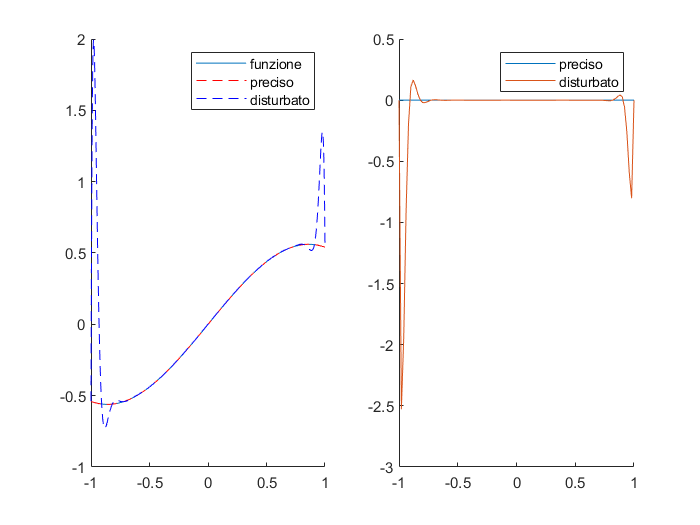

clear all
close all
f=@(x) x.*cos(x);
a=-1;b=1;
n=22;
p=calcPoly([a b],n,f);
v=rand(1,n+1)*10^-3;
z=linspace(a,b,n+1);
ycap=v+f(z);
pe=polyfit(z,ycap,n);
figure
subplot(1,2,1)
hold on
fplot(f,[a b])
plotPoly(p,[a b],"--r")
plotPoly(pe,[a b],"--b")
legend("funzione","preciso","disturbato")
subplot(1,2,2)
hold on
N=100;
z=linspace(a,b,N);
fz=f(z);
yp=polyval(p,z);
yd=polyval(pe,z);
ep=fz-yp;
ed=fz-yd;
plot(z,ep,z,ed)
legend("preciso","disturbato")

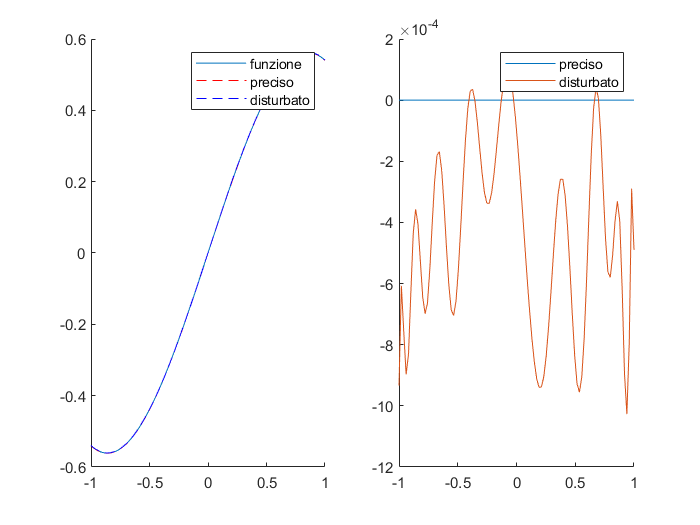

f=@(x) x.*cos(x);
a=-1;b=1;
n=22;
p=calcPoly([a b],n,f);
v=rand(1,n+1)*10^-3;
[pe,xc]=chebyshev(n,a,b,f);
ycap=v+f(xc);
pe=polyfit(xc,ycap,n);
figure
subplot(1,2,1)
hold on
fplot(f,[a b])
plotPoly(p,[a b],"--r")
plotPoly(pe,[a b],"--b")
legend("funzione","preciso","disturbato")
subplot(1,2,2)
hold on
N=100;
z=linspace(a,b,N);
fz=f(z);
yp=polyval(p,z);
yd=polyval(pe,z);
ep=fz-yp;
ed=fz-yd;
plot(z,ep,z,ed)
legend("preciso","disturbato")